clc
clear all

Fc = 60; %frequency 60Hz
Av =1;  % amplitude
Ts = 0.0005; % 1/0.0005 = 2 kHz  campionamento
StopTime = 0.1;             % seconds
t = (0:Ts:StopTime-Ts)';     % seconds
omega = 2*pi*Fc; % angular frequency constant over time

%============= Model is at steady state ===========
A =  [1 0; 0 1]; % valori paper: A = eye(2);
B = [0;0]; % valori paper: B = 0;
C =  [cos(omega*t), -sin(omega*t)];  % frequenza di 60Hz
D = 0;

%se x1(0)= A*cos(phi) = x2(0)= A*sin(phi) --> phi = 45°
x1 = 1*cos(pi/4);     %x1 = Av*cos(phi);
x2 = 1*sin(pi/4);     %x2 = Av*sin(phi);
x = [x1;x2];
Av = 1;
signal = cos(omega*t)*x1 - sin(omega*t)*x2; % y (outout plant)
% signal = Av*cos(omega*t)*cos(0) - Av*sin(omega*t)*sin(0); % y (outout plant)

Q = eye(2); %state noise covariance
R = 1;  % measurement noise covariance


SIGNAL WITHOUT NOISE

%filtered0 = funzioneBella(signal, Q, R, 0.1,x);
% figure(1)
% plot(t, signal, 'green', t, filtered0, 'red');
% ylim([-1.5,1.5]);
% grid on;

[filtered0, residue0, covariance0, p0] = funzioneBella(signal, Q, R, 0.1);

SIGNAL WITH NOISE

%add a random noise on the signal
signal_disturbed = signal + 0.02 * randn(size(signal)); 

[filtered, residue, covariance, p, K, x_hat,P1] = funzioneBella(signal_disturbed, Q, R, 0.1);
filtered = filtered';

figure(1)
subplot(311)
plot(t, signal_disturbed, 'blue', t, filtered, 'red');
ylim([-1.5,1.5]);
legA = legend('real','estimated');
set(legA,'FontSize',12)
title('chi detector without attack');grid on;

% g_prova = residue'*inv(cov(residue))*residue
r = signal_disturbed - filtered;
% CHI SQUARED
g = compute_g(C, t, P1, residue);

figure(1)
subplot(312)

% plot(t, cumsum(r));
plot(t, g');
ylim([-0.5,4]);
yline(3,'-.k','Threshold');

% EUCLIDIAN
euc0 = euclidean_distance(signal_disturbed, filtered, t);
% euc0= 0;
% for i=1:max(size(signal))
%    euc0(i)= norm(filtered(i)-signal_disturbed(i));
% end

figure(1)
subplot(313)
plot(t,euc0,'black');
yline(0.6,'-.k','Threshold');


% Check if the fault changes the residual (lo fa il prof, senza attacco è 0
% con attacco è 1
isequal(residue0, residue) 

ans = logical
   0



% figure()
% plot(residue)
% plot(r)


Add a  FDIA - Random case (without selecting tau)

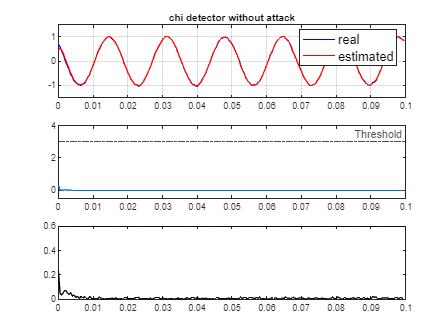

% signal_attacked = signal_disturbed + ya
y = signal_disturbed; 
y_sfasato = Av*cos(omega*t- pi/6);
j = 2;
for i=100:198
    y(i) = y(i) + (j)*y_sfasato(i);
%     y(i) = y(i)+(j)*y(i);
    j=j-0.01;
end

[filtered_a, residue_a, covariance_a, p_a, k,x_hat,P1] = funzioneBella(y, Q, R, 0.1);
filtered_a = filtered_a';
r_a = signal_disturbed - filtered_a;


figure(2)
subplot(311)
plot(t, signal_disturbed, 'blue', t, filtered_a, 'red');
ylim([-2,2]);
set(legA,'FontSize',12)

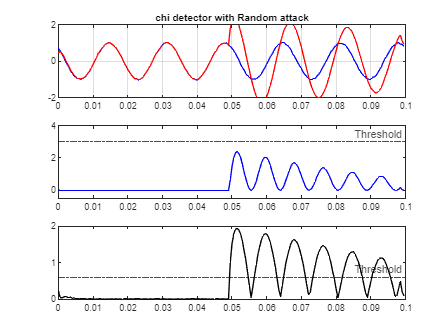

title('chi detector with Random attack');grid on;

g = compute_g(C, t, P1, r_a);

figure(2);
subplot(312);
plot(t, g, 'blue');
ylim([-0.5,4]);
yline(3,'-.k','Threshold');


% o= inv(cov(r_a))
% g_prova=0;
% for i=1:length(t)
% g_prova(i) = r_a(i)*o*r_a(i)';
%  end
% % g_prova = r_A*o*r_A'
% b=chi2pdf(r_a,4)
% a=chi2pdf(g_prova,4)

% figure()
% plot(t, cumsum(-r_a));   %CHI SQUARED
% yline(0,'-');
% yline(3,'-.k','Threshold');
% grid on;
% plot(t,b)
% plot(t,g_prova)
% plot(t,a)

%EUCLIDIAN
euc = euclidean_distance(signal_disturbed, filtered_a, t);

figure(2)
subplot(313)
plot(t,euc,'black');
yline(0.6,'-.k','Threshold');


% % CHECK CONDITIONS TO BE UNDETECTED
% % ||delta r|| sempre <=1 


% EXTRA
% Check if the fault changes the residual
isequal(residue, residue_a) 

ans = logical
   0


NonRandom FDIA

ya(n+t)= ya(t) - (lamba^(i+1))/M *y_star

% % function [signal_attacked] = addAttack(signal,residue)
v = [1;0];
lambda = 1;
y_star = C*v

y_star =     1.0000
    0.9823
    0.9298
    0.8443
    0.7290
    0.5878
    0.4258
    0.2487
    0.0628
   -0.1253


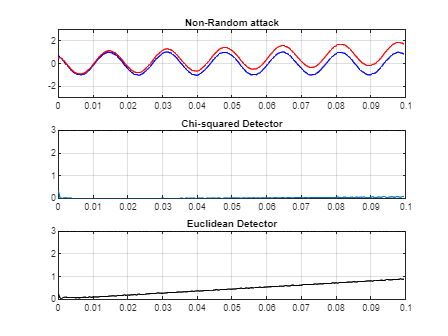

n = 2; %dimension of state space

% M = max(r);
% y = signal_disturbed; 
% for i=1:200
%     y(i) = y(i)+t(i)*10;
% end
% 

% attack1 = C * [t, t]'; 
% D = diag(0,1,0,1)
attack_vector = zeros(size(y));
% for i=1:length(t)-2
%      attack_vector(2+i) = attack_vector(i) - (1^(i + 1)/0.3)*y_star(i);
% end
% y_sfasato2 = Av*cos(omega*t- pi/6);

y = signal_disturbed;
for i=1:length(t)
    y(i) = y(i) + t(i)*10;
end

[filtered_A, residue_A, covariance_A, p_A, KA, x_hatA,P3] = funzioneBella(y, Q, R, 0.1);
filtered_A = filtered_A';
x = zeros(200,2);
x(:,1)=x1;
x(:,2)=x2;
% r_A = signal - filtered_A;
% r_A = abs(r_A(:,1)) -abs(r_A(:,2));
% r_A =x - x_hatA;
% norm(r_A)
% r_A = -signal_disturbed + filtered_A;

% EUCLIDIAN
eucA = euclidean_distance(signal_disturbed, filtered_A, t);

figure(3)
subplot(311)
plot(t, signal_disturbed, 'blue', t, filtered_A, 'red');
ylim([-3,3]);
% set(legA,'FontSize',12);
title('Non-Random attack');grid on;

% o= inv(cov(r_A));
% g_prova=0;
% for i=1:length(t)
% g_prova(i) = r_A(i)*o*r_A(i)';
%  end
% g_prova = r_A*o*r_A'
% 
% b=chi2pdf(r_A,4)
% a=chi2pdf(g_prova,4)
% figure()
% plot(t,b)
% plot(t,a)
% plot(t,g_prova)
r_A = residue_A;
g3 = compute_g(C, t, P3, r_A);

figure(3)
subplot(312)
% plot(t, cumsum(r_A));
plot(t,g3)
yline(0,'-');
yline(3,'-.k','Threshold');
title('Chi-squared Detector');
grid on;

figure(3)
subplot(313)
plot(t, eucA,'black');
yline(0,'-');
yline(3,'-.k','Threshold');
title('Euclidean Detector');
grid on;


% amplitudes_signal = compute_amplitude(y, omega, pi/4, t);
% amplitudes_filtered = compute_amplitude((filtered_a'), omega, pi/4, t);
% 
% euc = euclidean_distance(amplitudes_signal, amplitudes_filtered, t);
% 
% 
% figure(4)
% plot(t, euc);


functions:

function [distance_vector] = euclidean_distance(amplitudes_signal, amplitudes_estimate, time)
    if (size(amplitudes_signal) ~= size(amplitudes_estimate))
        error('size of true signal and size of estimated signal are not equal');
    end
    distance_vector = zeros(size(amplitudes_signal));
    for t=1:length(distance_vector)
        p = [time(t) amplitudes_signal(t)];
        q = [time(t) amplitudes_estimate(t)];
        %distance_vector(t) = sqrt((amplitudes_signal(t) - amplitudes_estimate(t)^2));
        %distance_vector(t) = sqrt((p(1) - q(1))^2 + (p(2) - q(2))^2); % formula della distanza tra due punti
        distance_vector(t) = dtw(p, q, 'euclidean');
    end
end


function [amplitudes] = compute_amplitude(signal, omega, phi, time)
    amplitudes = zeros(size(signal));
    
    for n=1:length(time)
        amplitudes(n) = signal(n) / (cos(omega*time(n)) * cos(phi) - sin(omega*time(n)) * sin(phi)); % inversa per trovare A, forse l'errore è phi costante
      
    end
end

function [g] = compute_g(C, time, P1, residue)
    for i=1:length(time)
        g_prova(i) = C(i,:) * P1(:,:,i) * C(i,:)';
    end
    for i=1:length(time)
        g(i) = residue(i) * g_prova(i) * residue(i);
    end
end
